ds_rate={'ori','ds2','ds5','ds10','ds20','ds50','ds100'}

ds_rate = 1×7 cell 배열
    {'ori'}    {'ds2'}    {'ds5'}    {'ds10'}    {'ds20'}    {'ds50'}    {'ds100'}


s=1

s = 1

e=3000

e = 3000

for i=1:length(ds_rate)
    expression=strcat("pk=norm_24.",ds_rate{i},"_rpm;");
    eval(expression);
%     me=mean(pk);
%     pk=pk/me;

    l=30;

    %평균
    tr(1)=mean(pk)-l;
    %분산
    tr(2)=var(pk);
    %왜도
    tr(3)=skewness(pk);
    %kurtosis
    tr(4)=kurtosis(pk);
    %max
    tr(5)=max(pk)-l;
    %min
    tr(6)=min(pk)-l;
    %median
    tr(7)=median(pk)-l;

    expression=strcat("B",num2str(i),"=tr;");
    eval(expression);
end

qq=10

qq = 10

C = vertcat(B1,B2,B3,B4,B5,B6,B7)

C =    -5.8159    1.8986   -0.1499    1.5450   -3.6319   -8.1401   -5.6694
   -5.8158    1.8991   -0.1497    1.5458   -3.6198   -8.1530   -5.6711
   -5.8159    1.9072   -0.1458    1.5574   -3.5254   -8.1697   -5.7214
   -5.8164    1.9400   -0.1321    1.5996   -3.3335   -8.1780   -5.7280
   -5.8145    2.0738   -0.1083    1.7232   -2.6424   -8.2046   -5.3025
   -5.7727    3.3557    0.3443    2.2902   -2.5573   -8.2638   -5.7410
   -5.6115    7.3389    0.1285    1.0259   -2.4566   -8.3305   -8.1317


% C=transpose(C)

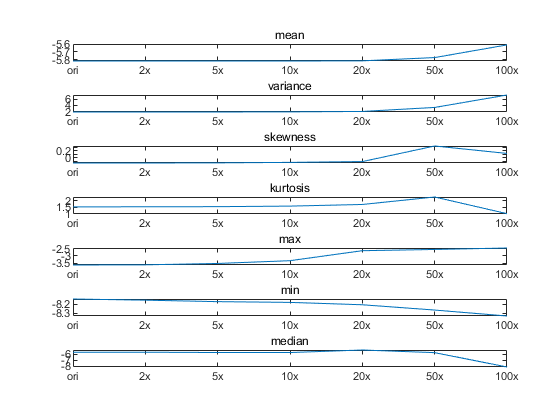

subplot(7,1,1)

plot(C(:,1));
title('mean')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

subplot(7,1,2)

plot(C(:,2));
title('variance')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

subplot(7,1,3)

plot(C(:,3));
title('skewness')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

subplot(7,1,4)

plot(C(:,4));
title('kurtosis')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

subplot(7,1,5)

plot(C(:,5));
title('max')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

subplot(7,1,6)

plot(C(:,6));
title('min')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

subplot(7,1,7)

plot(C(:,7))
title('median')
% ylim([0,qq])
xticks(1:1:7)
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})

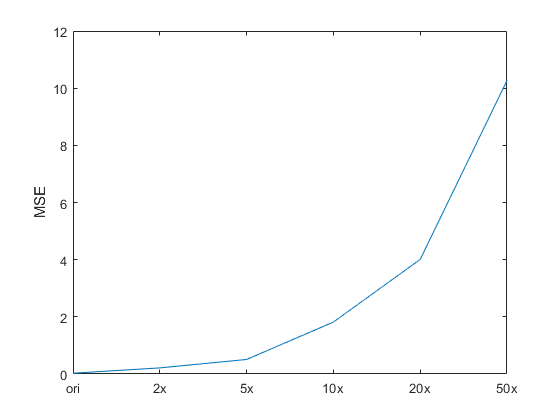

f2=figure;
cost_2(1)=sum(abs(C(1,:)-C(2,:)));
cost_2(2)=sum(abs(C(1,:)-C(3,:)));
cost_2(3)=sum(abs(C(1,:)-C(4,:)));
cost_2(4)=sum(abs(C(1,:)-C(5,:)));
cost_2(5)=sum(abs(C(1,:)-C(6,:)));
cost_2(6)=sum(abs(C(1,:)-C(7,:)));

plot(cost_2)

xticks(1:1:6)
ylabel("MSE")
xticklabels({'ori','2x','5x','10x','20x','50x','100x'})